Logarithmic Regression

Sometimes there is a quasi linear connection between our inputs(independent variable) and our outputs(dependent variable).

Let's see the following example

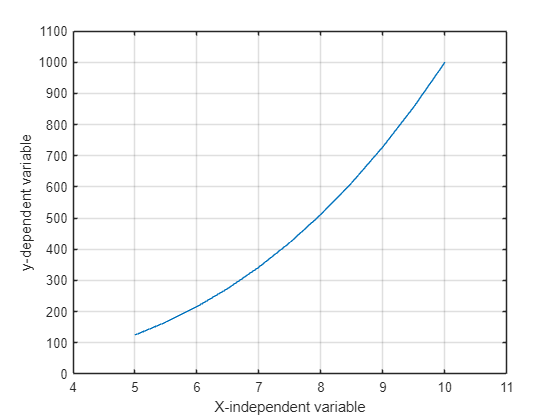

X = 5:0.5:10; 
y = X .^3;
figure
plot(X, y, DisplayName="y=x^3")
grid on
xlabel('X-independent variable')
ylabel('y-dependent variable')
xlim([4, 11])
ylim([0, 1100])

We can see that out date follows a "linear" trend, so, using the previous code, let's fit a linear regression model:


$$y = w * x+ b$$
 

[w, b] = ordinary_least_squares(X, y);

w = 173.2000

b = -820.8750

Let's visualize our model's results and also calculate the root mean square error of our model.

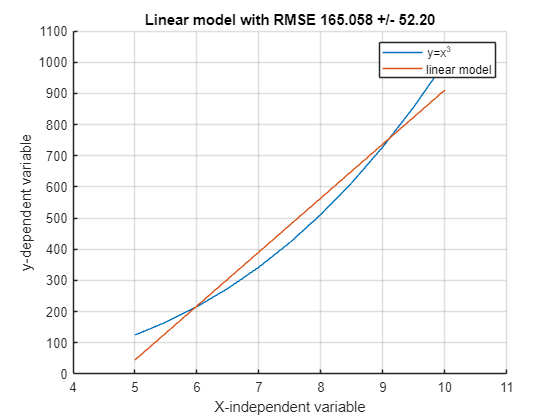

y_hat = w * X + b;
[error, error_std] = rmse(y, y_hat);
figure
hold on
plot(X, y, DisplayName="y=x^3")
plot(X, y_hat, DisplayName="linear model")
grid on
xlabel('X-independent variable')
ylabel('y-dependent variable')
legend()
title_text = sprintf("Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([4, 11])
ylim([0, 1100])

From a visual perspective, it is clear that our model **fails** to capture the data, eventhough, the RMSE is relatively **low**.

## How can we find a better way to fit our data?

### There are 2 solutions:

- Transform our problem to a **logarithmic** one,

- Add more **polynomial variables-features as input **to the model

### **Logarithmic transformation:**

If our linear model can't fit the data, then there might be some exponential relation between our X and y values.

Let's transform our data:

x_log = log(X);
y_log = log(y);

Let's visualize the new data

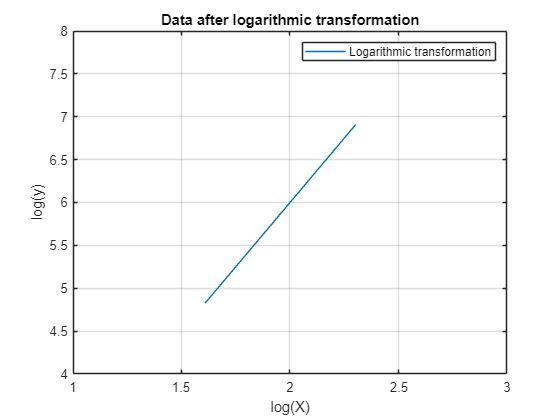

figure
plot(x_log, y_log, DisplayName="Logarithmic transformation")
grid on
xlabel('log(X)')
ylabel('log(y)')
legend()
title_text = sprintf("Data after logarithmic transformation");
title(title_text);
xlim([1, 3])
ylim([4, 8])

We can clearly see that the new data follow a more linear trend let's try and fit a linear model to this data

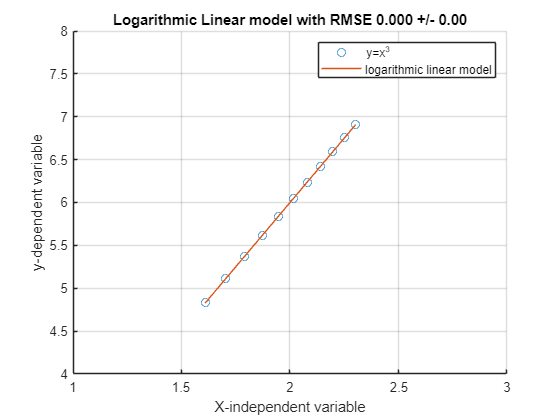

[w_log, b_log] = ordinary_least_squares(x_log, y_log);
y_log_hat = w_log * x_log + b_log;
[error, error_std] = rmse(y_log, y_log_hat);
figure
hold on
plot(x_log, y_log, 'o',DisplayName="y=x^3")
plot(x_log, y_log_hat, DisplayName="logarithmic linear model")
grid on
xlabel('X-independent variable')
ylabel('y-dependent variable')
legend()
title_text = sprintf("Logarithmic Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([1, 3])
ylim([4, 8])

Is the above plot correct? What should we change?

Our results are on the logarithmic scale and this might make it hard to interpret them. We need to transform them back to the original scale.

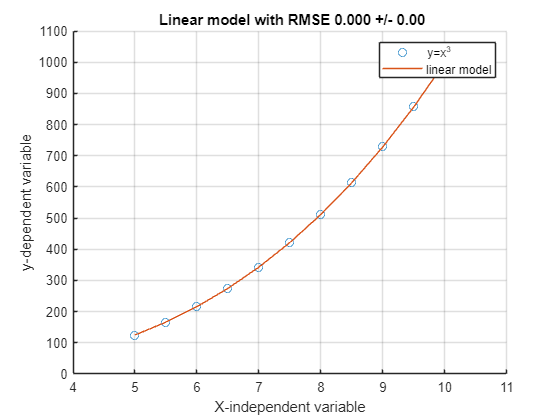

y_hat_rescaled = exp(y_log_hat);
[error, error_std] = rmse(y, y_hat_rescaled);
figure
hold on
plot(x, y, 'o',DisplayName="y=x^3")
plot(x, y_hat_rescaled, DisplayName="linear model")
grid on
xlabel('X-independent variable')
ylabel('y-dependent variable')
legend()
title_text = sprintf(" Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([4, 11])
ylim([0, 1100])

### **Add Polynomial features/variable to our inputs:**

Sometimes we might know that our outputs depend on differenent **powers** of the input variable. 

In the case of mutli-regressions there might be some **interaction** terms as well. 

Since we are about to increase the size of our input we will go from a simple linear model:


$$y = w * x+ b$$
 

to the multi-linear model:


$$y = w_n * x_n + w_{n-1}*x_{n-1}+...+ w_1*x_1 +w_0$$
 

where $w_0 =b$

The multi-linear regression makes the same assumptions about the data, but the way of acquiring the best weight $w_i$ requires some iterative process which is beyond the scope of the lecture. 

X_2 = X.^2;
X_3 = X.^3;
X_power = [ones(size(X)); X; X_2; X_3; X_4];

To perform the multi-linear regression in matlab we can simple use the regress function.

If we specify the requested outputs we can also get some usefull statistics of our model!

[b,bint,r,rint,stats] = regress(y', X_power');

Let's see the weights/coefficients that our model returned

b

b =     0.0000
   -0.0000
    0.0000
    1.0000
    0.0000


We can see that our model found out that only the $X^3$ term was usefull and thus all the other weights went to 0. Lets visualize the results

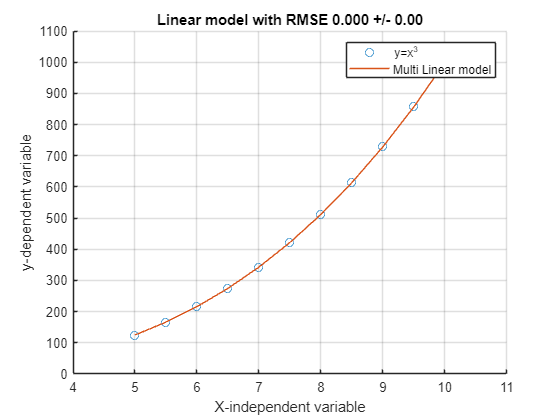

y_multi_hat = X_power' * b;
[error, error_std] = rmse(y, y_multi_hat');
figure
hold on
plot(X, y, 'o', DisplayName="y=x^3")
plot(X, y_multi_hat, DisplayName="Multi Linear model")
grid on
xlabel('X-independent variable')
ylabel('y-dependent variable')
legend()
title_text = sprintf("Linear model with RMSE %0.3f +/- %0.2f", error, error_std );
title(title_text);
xlim([4, 11])
ylim([0, 1100])

Let's see an example with the polyfit and polyval function, and what are some pitfalls of the polynomial features.

rng("default") % to reproduce the example below.
n_samples = 30;
x = sort(rand(n_samples, 1));
y = true_fuction(x) + randn(n_samples, 1) * 0.1;

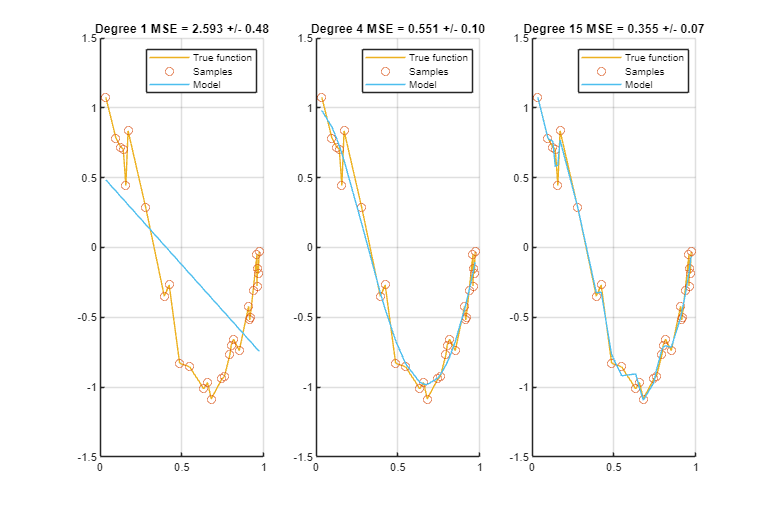

warning('off')

N = [1, 4, 15];
tiledlayout(4,5);
for case_id=1:3
    n = N(case_id);
    polynomial_coefs = polyfit(x, y, n);
    y_hat = polyval(polynomial_coefs, x);
    [error, error_std]  = rmse(y, y_hat);
    subplot(1, 3, case_id)
    hold on
    p = plot(x, y, DisplayName="True function");
    p.Color = "#EDB120";
    p = scatter(x, y, DisplayName="Samples ");
    p.ColorVariable = "#0072BD";
    p = plot(x, y_hat, DisplayName="Model");
    p.Color = 	"#4DBEEE";
    grid on
    legend()
    title_text = sprintf("Degree %0.f MSE = %0.3f +/- %0.2f", n, error, error_std );
    title(title_text);
end

set(gcf, 'position', [10,10, 1080, 720])

#### QUESTIONS:

- Add noise to the two previous examples and see which one of the two methods performs better.

- Using the data provided in the sea_trials.csv, try to predict the Power variable using:

                a) Only the STW variable in a logarithmic model,

                b)  Only the STW variable in a polynomial feature model,

                c) All the other variables, STW, T_aft, T_fwd, Wind_Speed and Wind_Direction in a multilinear model,

                d) All the other variables, STW, T_aft, T_fwd, Wind_Speed and Wind_Direction in a ridge multilinear model.

                You can try any data transofmation you like, to achieve better results.

        Test the models' performance on the test_data.csv, what do you notice about the error and the models, and what are some possible explanations?

function [w, b] = ordinary_least_squares(X, Y)
    N = size(X, 2);
    x_squared_sum = sum(X.^2);
    x_y_sum = sum(X .* Y);
    x_sum = sum(X);

    y_sum = sum(Y);
    x_sum_squared = x_sum ^ 2/ N;

    w = (x_y_sum - (x_sum*y_sum)/N) / (x_squared_sum - x_sum_squared);
    b = y_sum / N - w * x_sum/N;

end

function [y] = true_fuction(x)

    y = cos(1.5 * pi *x);
end

function [error, error_std] = rmse(y, y_hat)
    error = round(sqrt(sum((y - y_hat).^2)), 3);
    error_std = round(std(y - y_hat), 3);
end